# Create Data

## Preparation

clc, clear
close all

## PDE Definition and Condition Setting

### PDE(wave equation)


$$\frac{\partial^2 \psi(x,y,t)}{\partial t^2} = c^2\lbrace\frac{\partial^2 \psi(x,y,t)}{\partial x^2}+\frac{\partial^2 \psi(x,y,t)}{\partial y^2}\rbrace$$


c = 0.6;                           % Propagation Velocity c

%% Spatial Mesh
% x
L_x = 3;                           % Maximum value in spatial direction
dx = 0.01;                         % Spatial displacement
N_x = floor(L_x/dx);               % Total number of spatial mesh
X_c = linspace(0,L_x,N_x);         % Coordinates (plot:N_x,range[0 L_x])
% y(same as x)
L_y = 3;
dy = 0.01;
N_y = floor(L_y/dy);
Y_c = linspace(0,L_y,N_y);

[X, Y] = meshgrid(X_c, Y_c);

%% Temporal Mesh
L_t = 7;                           % Maximum value in spatial direction
dt = 0.01;                         % Temporal displacement
N_t = floor(L_t/dt);               % Total number of temporal mesh

## Dataset Creation 

### Definition of Initial Conditions

A = 10;          % Amplitude
sigma = 0.005;                          % Width of the initial wave packet

x_0 = 1.5;       % Initial position x0 
y_0 = 1.5;       % Initial position y0

%% One epicenter
u0 = A * exp(-((X - x_0).^2 + (Y - y_0).^2)/(2 .* sigma^2));

% Four epicenters equally spaced
% u0 = 0;
% for m = 1:2
%     for n = 1:2
%          u0 = u0 + A * exp(-((X - (0.75 + 1.5*(n-1))).^2 + (Y - (0.75 + 1.5*(m-1))).^2)/(2 .* sigma^2));
%     end
% end

% Four epicenters equally spaced (Another)
% for n = 1:2
%     u0 = u0 + A * exp(-((X - (0.25 + 0.5*(n-1))).^2 + (Y - 0.5).^2)/(2 .* sigma^2));
% end
% for m = 1:2
%     u0 = u0 + A * exp(-((X - 0.5).^2 + (Y - (0.25 + 0.5*(m-1))).^2)/(2 .* sigma^2));
% end

### Creating a Dataset from PDE Solutions

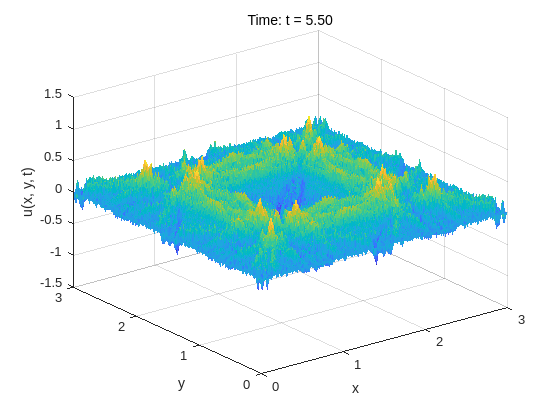

u = zeros(N_x ,N_y ,N_t);    

u(:,:,1) = u0;       % Assignment of initial conditions
u_dt = zeros(size(u0));

%% Solving PDEs by finite difference method
for n = 2:N_t-1
    for i = 2:N_x-1
        for j = 2:N_y-1
            u(i, j, n+1) = 2*u(i, j, n) - u(i, j, n-1) + c^2 * dt^2 * ...
                ((u(i+1, j, n) - 2*u(i, j, n) + u(i-1, j, n)) / dx^2 + ...
                 (u(i, j+1, n) - 2*u(i, j, n) + u(i, j-1, n)) / dy^2);
        end
    end
%% Dirichlet boundary condition
    u(1, 1:end, n+1) = 0;       % Bottom
    u(end, 1:end, n+1) = 0;     % Top
    u(1:end, 1, n+1) = 0;        % Left
    u(1:end, end, n+1) = 0;      % Right
end

[Xs, Ys] = meshgrid(X_c, Y_c);

%% Data Extraction
T_st = 400 + 1;
T_en = 550;
u = u(:,:,T_st:T_en);

for n = 1:size(u,3)
    surf(Ys, Xs, u(:, :, n)', 'EdgeColor', 'none');
    axis([0 L_x 0 L_y -1.5 1.5]);
    xlabel('x');
    ylabel('y');
    zlabel('u(x, y, t)');
    title(sprintf('Time: t = %.2f', (T_st - 1 + n)*dt));
    pause(0.01);
end

%% Save data
save('./Experience1/Dataset/data0.mat','u')

## Observation of data snapshots

for n = 1:size(u,3)
if floor((T_st-1 + n)*dt) == (T_st-1 + n)*dt
    disp_imagesc_(Ys,Xs,u(:,:,n));
    title("Plot of Wave Equation: t = "+ num2str((T_st-1 + n)*dt),'FontSize',18)
    exportgraphics(gcf,"./Experience2/Snapshot/data2/TimeVariation_"+"t_" + num2str((T_st-1 + n)*dt) + ".png");
else
end    
end

Observation of data snapshots

function disp_imagesc_(Y,X,DataT)
imagesc(DataT)
colormap("jet")
colorbar
xlabel('x','FontSize',20)
ylabel('y','FontSize',20)
ax = gca;
ax.PlotBoxAspectRatio = [1 1 1];
ax.XTick = linspace(0,size(X,2),5);
ax.XTick(1) = 1;
ax.XTickLabel = round(X(1,ax.XTick),1);
ax.YTick = linspace(0,size(Y,1),5);
ax.YTick(1) = 1;
ax.YTickLabel = round(Y(ax.YTick,1),1);
ax.YDir = 'normal';
clim([-1 1]);
ax.FontSize = 18;
end